# Tde 03Feb2022

## Q3

clear;
clc;

syms q1 q2 q3 q1dot q2dot q3dot
qv = [q1 q2 q3];
qvdot = [q1dot q2dot q3dot];
c123 = cos(q1+q2+q3);
s123 = sin(q1+q2+q3);
c12 = cos(q1+q2);
s12 = sin(q1+q2);
c1 = cos(q1);
s1 = sin(q1);
q123dot = q1dot+q2dot+q3dot;
q12dot = q1dot+q2dot;

% 3R robot inverse kinematics for qdotdot
p = [cos(q1)+cos(q1+q2)+cos(q1+q2+q3);
    sin(q1)+sin(q1+q2)+sin(q1+q2+q3)];
Jq = jacobian(p,qv)
% time derivative of the jacobian is incorrect because of 
% matlab incapability of considering q time dependent without
% making a mess
% J2 = diff(Jq)
J2 = [-q123dot*c123-q12dot*c12-q1dot*c1 -q123dot*c123-q12dot*c12 -q123dot*c123;
    -q123dot*s123-q12dot*s12-q1dot*s1 -q123dot*s123-q12dot*s12 -q123dot*s123];
n = J2*qvdot'

J3 = [-s123-s12-s1 -s12-s123 -s123;
    c1+c12+c123 c12+c123 c123;
    1 1 1]
detJ3 = simplify(det(J3))

% point 3
qd = [pi/4 pi/3 -pi/2];
qddot = [-0.8 1 0.2];
pd = subs(p, qv, qd)
Jqd = simplify(subs(Jq, qv, qd));
pddot = eval(Jqd*qddot')
J4 = eval(subs((J3), qv, qd))
n = eval(subs(n, qv, qd));
n = eval(subs(n, qvdot, qddot))
qdotdot = inv(J4)*[[1 1]'-n; 0]

% point 4

## Q4

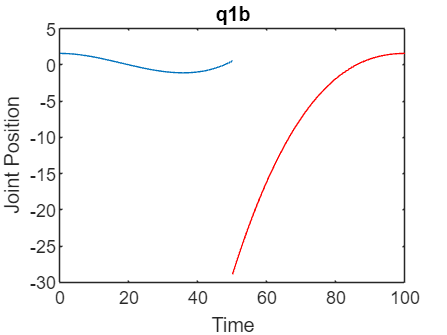

% Define the points (replace with actual values)
T = 100;
ta = [0, T/2]; % Time points
tb = [T/2, T]; % Time points
q_start1 = 0; % Start position
q_mid1 = 0.5318; % Mid position
q_end1 = 3; % End position
q_start2 = pi/2;
q_mid2 = 0.2527;
q_end2 = pi/2;

% Create the spline
spline_traja1 = spline(ta, [q_start, q_mid]);
spline_traja2 = spline(ta, [q_start, q_mid]);
spline_trajb1 = spline(tb, [q_start, q_mid]);
spline_trajb2 = spline(tb, [q_mid, q_end]);

% Evaluate the spline at a range of points
t_eval1 = linspace(0, T/2, 100);
t_eval2 = linspace(T/2, T, 100);

q_evala1 = ppval(spline_traja1, t_eval1);
q_evala2 = ppval(spline_traja2, t_eval2);

q_evalb1 = ppval(spline_trajb1, t_eval1);
q_evalb2 = ppval(spline_trajb2, t_eval2);

% Plot the trajectory
figure
plot(t_eval1, q_evala1);
xlabel('Time');
ylabel('Joint Position');
title('q1a');
hold on
plot(t_eval2, q_evalb1, 'r');
xlabel('Time');
ylabel('Joint Position');
title('q1b');

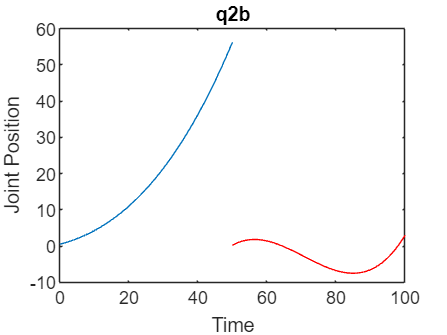


figure
plot(t_eval1, q_evala2);
xlabel('Time');
ylabel('Joint Position');
title('q2a');
hold on
plot(t_eval2, q_evalb2, 'r');
xlabel('Time');
ylabel('Joint Position');
title('q2b');

[cofs, vels] = splines(tvals, qvals);

coeffs = splines_norm_compute_coeffs(tvals, qvals, v1, vn, print_info)
spline_plot_norm(tvals, coeffs)

